# Problem 1

The support for a certain mechanism hangs from the ceiling. As seen in the Figure, it consists of two parts of square ccross-sections: of length $h_{1} = 2$ and area section $A_{1} = 1$ at the top, and length $h_{2}$=1 and area $A_{2} = 2$ at the bottom. Only for academic purposes, we assume that the material has modulus of elasticity $E = 1$and the specific weight is $\omega = 1$. We want to study the elastic deformation due to **own weight** of the piece with the FEM with a linear element in the upper part, and a quadratic on the lower part, as shown in the figure. 

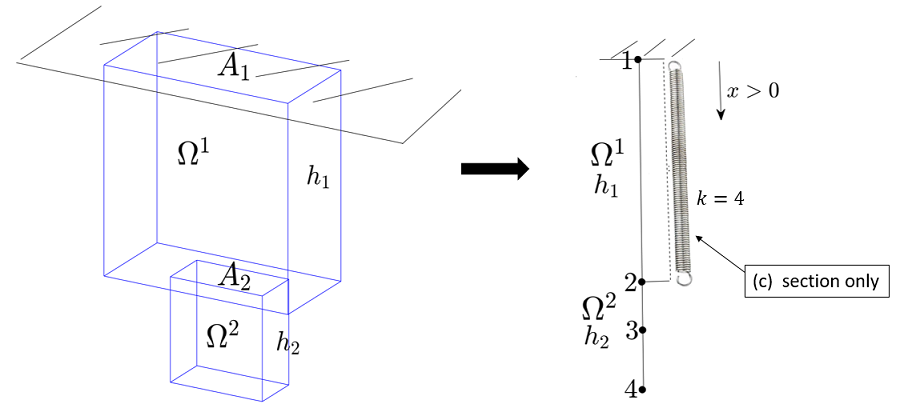

Answer the following questions.

clearvars
close all
%Data
h1 = 2; A1 = 1;
h2 = 1; A2 = 2;
E = 1;
w = 1;
kappa = 4; % spring ctnt (for part (c))

#### (a) (2 points)

The entry $K_{2,2}$ of the stiff matrix of the global assembled system is (*Hint.* The value of $K_{23}$is $K_{23} =$ -5.3333e+00)

**Solution:**

The local stiffness matrices are,

 $K^{1} = \frac{A_{1}E}{h_{1}}\left(\begin{array}{rr}
1 & -1 \\
-1 & 1
\end{array}\right) = \frac{1}{6}\left(\begin{array}{rr} 
3 & -3\\
-3 & 3
\end{array}\right),\qquad 
K^{2} = \frac{A_{2}E}{3 h_{2}}\left(\begin{array}{rrr}
7 & -8 & 1 \\
-8 & 16 & -8 \\
1 -& -8  & 7
\end{array}\right) = \frac{1}{6}
\left(\begin{array}{rrr} 
28 & -32 & 4\\
-32 & 64 & -32 \\
4 & -32 & 28
\end{array}\right)$,

for the first and the second elements respectively. So the Global stiffness matrix is, after assembling,

$K = \frac{1}{6}\left(\begin{array}{rrrr}
3 & -3 & 0 & 0\\
-3 & 31 & -32 & 4 \\
0  & -32 & 64 & -32\\
0 & 4 & -32 & 28
\end{array}\right)
$.

So  $K_{22} = 31/6 = 5.1667$ and (hint.) $K_{23} = -32/6 = -5.3333$.

K1 = A1*E*[1,-1;-1,1]/h1;
K2 = A2*E*[7,-8,1;-8,16,-8;1,-8,7]/h2/3;
K = zeros(4);
K(1:2,1:2) = K1;
K(2:4,2:4) = K(2:4,2:4) + K2;
fprintf(['K(2,2) = %.4e\n','Hint. K(2,3) = %.4e\n'],K(2,2),K(2,3))

K(2,2) = 5.1667e+00
Hint. K(2,3) = -5.3333e+00


disp('Stiff matrix:'); K

Stiff matrix:


K =     0.5000   -0.5000         0         0
   -0.5000    5.1667   -5.3333    0.6667
         0   -5.3333   10.6667   -5.3333
         0    0.6667   -5.3333    4.6667


#### (b) (3 points)

The second component of the global assembled force, $F_{2}$ is (*Hint.* The valie of $F_{3}$ is $F_{3} =$1.3333e+00).

**Solution:**

The local load vectors are,


$$F^{1} = \frac{\omega A_{1}h_{1}}{2}\left(\begin{array}{r} 1\\ 1\end{array}\right) = 
\frac{1}{3}\left(\begin{array}{rr} 3\\ 3\end{array}\right),\qquad 
F^{2} =  \frac{\omega A_{2}h_{2}}{6}\left(\begin{array}{r} 1\\ 4 \\1\end{array}\right) = 
\frac{1}{3}\left(\begin{array}{rr} 1\\ 4\\ 1\end{array}\right),$$


for the first and the second element respectively, So the global load vector is, after assembling,

$F = \frac{1}{3}\left(\begin{array}{r} 3\\ 4\\ 4\\ 1\end{array}\right)$.

So $F_{2} = 4/3 = 1.3333$, and (hint.) $F_{3} = 1.3333$.

F1 = w*A1*h1*[1;1]/2;
F2 = w*A2*h2*[1;4;1]/6;
F = zeros(4,1);
F(1:2) = F1;
F(2:4) = F(2:4)+F2;
fprintf(['F(2) = %.4e\n','Hint. F(3) = %.4e\n'],F(2),F(3))

F(2) = 1.3333e+00
Hint. F(3) = 1.3333e+00


#### (c) (5 points)

Besides, we suppose that the bottom of the upper element is attached to a spring initially at rest and anchored at the ceiling and with recovering constant $\kappa = 4$. Then, the displacement $U_{3}$ of the global node $3$ is (you can use Hint. 3).

*Hint. *The value of $U_{4}$ is $U_{4} =$ 1.1667e+00.

**Solution:**

The assembled system is,


$$\frac{1}{6}\left(\begin{array}{rrrr}
3 & -3 & 0 & 0\\ 
-3 & 31 & -32 & 4\\
0 & -32 & 64 & -32\\
0 & 4 & -32 & 28
\end{array}\right)
\left(\begin{array}{c}
U_{1}\\
U_{2}\\
U_{3}\\
U_{4}\end{array}\right) =
\frac{1}{3}\left(\begin{array}{c} 3\\ 4\\ 4\\ 1\end{array}\right) +
\left(\begin{array}{c}
Q_{1}\\
Q_{2}\\
Q_{3}\\
Q_{4}\end{array}\right).$$


and the boundary conditions are,

- Natural: $Q_{2} = \kappa U_{2} = -4 U_{2}$, $Q_{3} = Q_{4} = 0$.

- Essential: $U_{1} = 0$.

Therefore, the *reduced *system is:

$\frac{1}{6}\left(\begin{array}{rrr}
31 & -32 & 4 \\
-32 & 64 & -32\\
4 & -32 & 28
\end{array}\right)
\left(\begin{array}{r}
U_{2}\\
U_{3}\\
U_{4}
\end{array}
\right) = \frac{1}{3}\left(\begin{array}{c}
4 \\
4\\
1\end{array}\right) +
\left(\begin{array}{c} -4 U_{2}\\ 0 \\0\end{array}\right)

\Longleftrightarrow 
\left(\begin{array}{rrr}
55 & -32 & 4 \\
-32 & 64 & -32\\
4 & -32 & 28
\end{array}\right)
\left(\begin{array}{r}
U_{2}\\
U_{3}\\
U_{4}
\end{array}
\right) = \left(\begin{array}{c}
8 \\
8\\
2\end{array}\right)$.

And, after solving this system one finds, for the displacements


$$U_{1} = 0,\quad
U_{2} = \frac{\left|\begin{array}{rrr}
8 & -32 & 4\\
8 & 64 & -32\\
2 & -32 & 28\end{array}
\right|}{
\left|\begin{array}{rrr}
55 & -32 & 4\\
-32 & 64 & -32\\
4 & -32 & 28\end{array}
\right|} = 
\frac{13824}{20736} = \frac{2^{9}\times 3^{3}}{2^{8}\times 3^{4}} = \frac{2}{3} = 0.\overline{6},\quad
U_{3} = \frac{\left|\begin{array}{rrr}
55 & 8  & 4\\
-32 & 8  & -32\\
4 & 2 & 28\end{array}
\right|}{
\left|\begin{array}{rrr}
55 & -32 & 4\\
-32 & 64 & -32\\
4 & -32 & 28\end{array}
\right|} = 
\frac{21600}{20736} = \frac{2^{5}\times 5^{2}\times 3^{3}}{2^{8}\times 3^{4}} = \frac{25}{24} = 1.041\overline{6},$$



$$U_{4} = \frac{\left|\begin{array}{rrr}
55 & -32 & 8\\
-32 & 64 & 8\\
4 & -32 & 2\end{array}
\right|}{
\left|\begin{array}{rrr}
55 & -32 & 4\\
-32 & 64 & -32\\
4 & -32 & 28\end{array}
\right|} = 
\frac{24192}{20736} = \frac{2^{7}\times 3^{3}\times 7}{2^{8}\times 3^{4}} = \frac{7}{6} = 1.1\overline{6}
$$


(where the first one $U_{1} = 0$ is given by the essential B.C.). So, the displacement of the third (global) node is $U_{3} = \frac{25}{24} = 1.041\overline{6}$ and (hint.) $U_{4} = \frac{7}{6} = 1.1\overline{6}$,

u = zeros(4,1);
Km = K(2:4,2:4);
Fm = F(2:4);
Km(1,1) = Km(1,1)+kappa;
um = Km\Fm;
u(2:4) = um;
fprintf(['U(3) = %.4e\n','Hint. U(4) = %.4e\n'],u(3),u(4))

U(3) = 1.0417e+00
Hint. U(4) = 1.1667e+00


nodes = [0;h1;h1+h2/2;h1+h2];
disp('Displacements:'); u

Displacements:


u =          0
    0.6667
    1.0417
    1.1667


U = array2table([nodes,u]);
U.Properties.VariableNames={'X','U'};
U

U = 4×2 table
     X        U   
    ___    _______

      0          0
      2    0.66667
    2.5     1.0417
      3     1.1667
